# **Battery Emulation**

This example shows you how to setup the IO992-06 I/O module, in order to emulate batteries and test your battery management system.

This I/O module offers 6 independent isolated channels for battery emulation and is typically used to emulate portable battery power supplies, battery stacks for electric vehicles or batteries under charge. Each channel can supply up to 7 V, source up to 300 mA and sink up to 300 mA. Multiple IO992 I/O modules can be combined in series or parallel to achieve the required power levels for charge and discharge (voltage and current).

The Simulink model features the [IO992 - Battery Control](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io99x_battery_control) block.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO992-06 I/O module installed

- Connector cable from the I/O module to the terminal board

- 37-pin terminal board with jumper wires

- Power Supply

- 2x 5 W 100 Ohm load resistor

### Test Setup

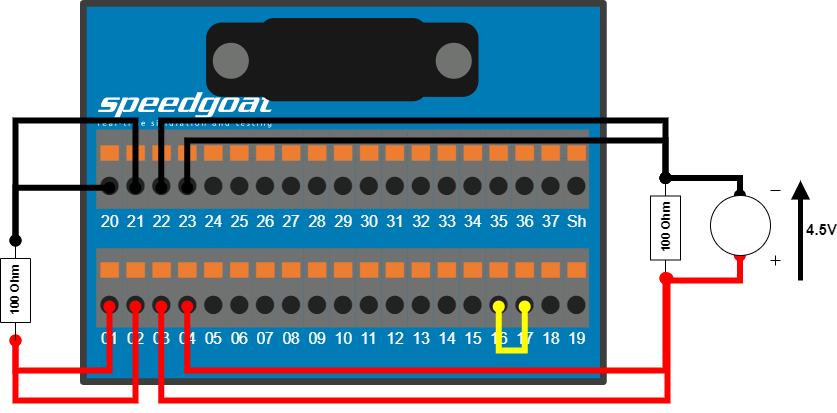

On the terminal board of the I/O module, connect a 100 Ohm resistor to channel one and two outputs as shown above. For channel two, connect a power supply as well with an output voltage of 4.5 V as this channel emulates a charging cell. To enable the outputs, connect the hardware input (Interlock) enable (pin 17) to 3.3 V (pin 16).

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_BatteryEmulation';
open_system(modelName);

### Model Description

In the model, channel one is used to simulate a discharging cell. The output voltage drops from the maximal value of 7 volts down to one. The measured current decreases as well due to the fixed load resistance of 100 Ohms.

Channel two is used to simulate a charging cell with a constant voltage and a decreasing charge current, starting at 200 mA. The output voltage of 4V is set lower as the externally connected power supply with 4.5 V to force the module to sink current.

The interlock output can be used to verify if the hardware input enable is active and therefore the outputs activated. Otherwise no output voltage is generated.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the IO992-06 works as expected, check the connected scopes. In the first scope the output voltages from channels one and two are displayed. Channel one must show a decreasing voltage and channel two a constant voltage of 4.5 V (The voltage might change, as the signal shows, at higher currents depending on the used power supply). The second scope shows the measured current. Channel one must show a decreasing current and channel two an increasing one, starting at -206.25 mA (Due to the fixed current sink steps of 18.75 mA, 200 mA is not available as used in the model).

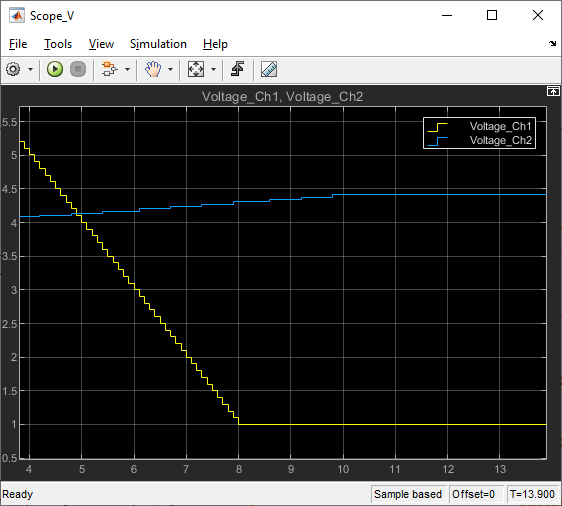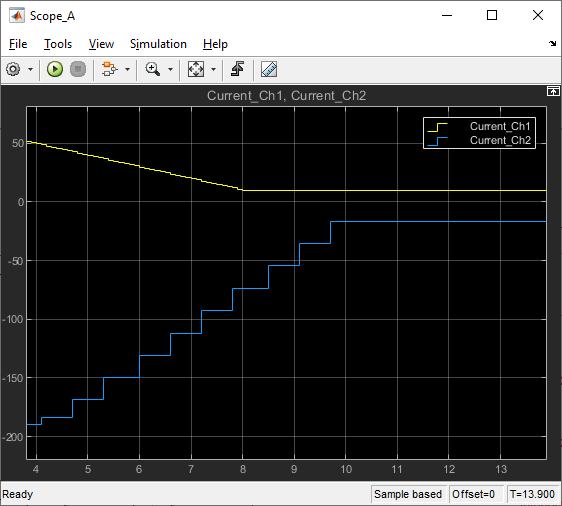

## Additional References

- [IO992 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io99x)